# `AnnulusChart`

**Overview**

The `AnnulusChart` comprises a ring, or annulus, divided into separate sections. There is one section for each element of the chart data (a nonempty numeric vector of positive values). Each section shows the contribution of the corresponding data value to the entire data set. The volume of each section is proportional to the contribution of the specific data value to the sum of the data values.

The wedges comprising the chart can be exploded individually via user interaction. Clicking on a wedge once will explode it radially outwards. Clicking on the same wedge a second time will restore its original position.

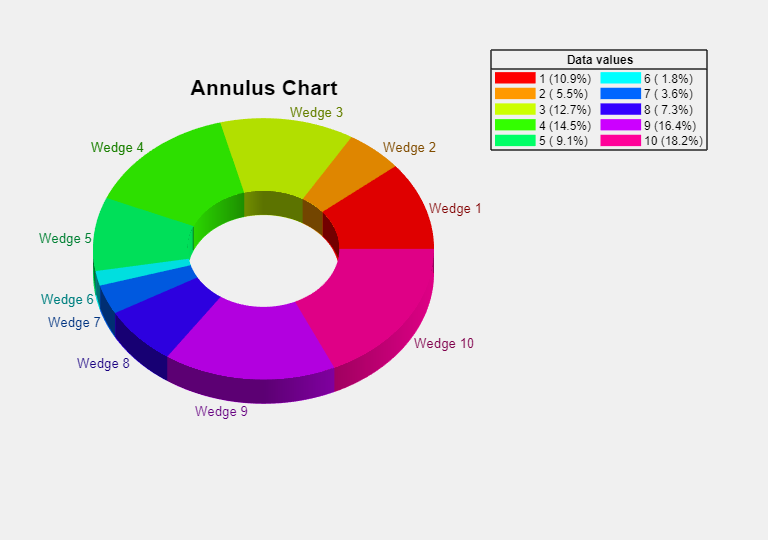

**Resources**

[Open](matlab: edit(fullfile(catalogRoot, "+example", "Annulus.mlx"))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(catalogRoot, "+chart", "Annulus.m"))) the source code for the `Annulus` chart.

Documentation for:

- [`surface`](matlab: doc("surface")): Primitive surface plot

- [`patch`](matlab: doc("patch")): Plot one or more filled polygonal regions

## Define the chart data.

The chart data comprises a nonempty numeric vector of positive values. For example, let's take a random permutation of the integers from 1 to 10.

rng( "default" )
data = randperm( 10 );

The chart accepts the vector data either as a row or a column, but it is stored within the chart as a column vector.

## Create a figure for the chart.

f = exampleFigure( "Name", "Annulus Example" );

## Create the chart.

Next, create the chart object, specifying the `Parent` and `Data` properties, and hiding the chart controls to begin with.

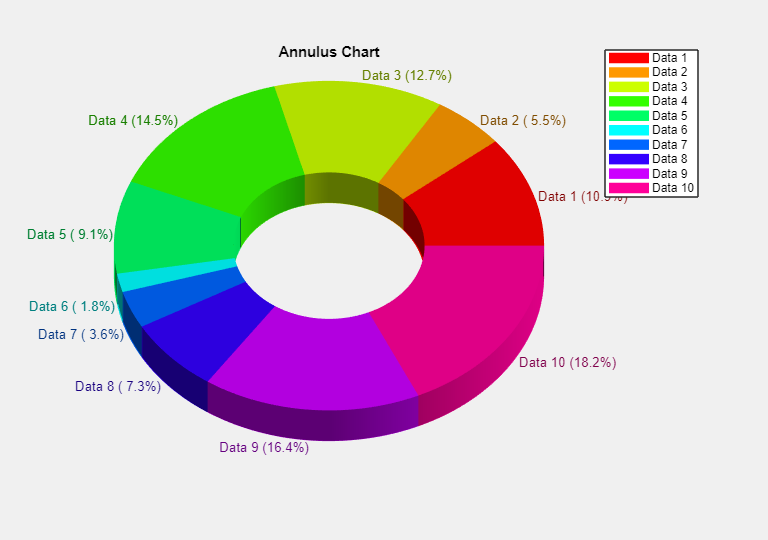

AC = AnnulusChart( "Parent", f, ...    
    "Data", data, ...
    "Controls", "off" );

The resulting chart has default wedge labels and legend entries of the form "`Data k`", where `k` is the corresponding data index.

## Annotate the chart.

The `Annulus` chart is equipped with the `title` method for annotation.

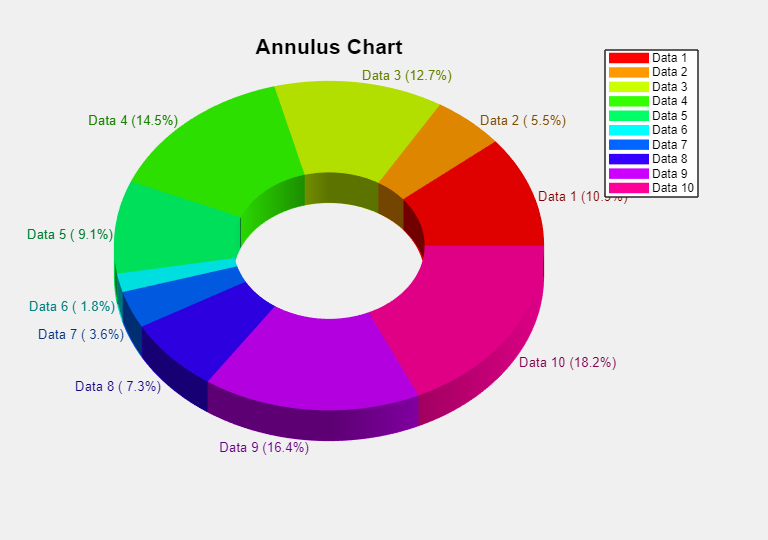

title( AC, "Annulus Chart", "FontSize", 16 )

## Change the wedge label text.

Specify some new text to use for labelling the wedges.

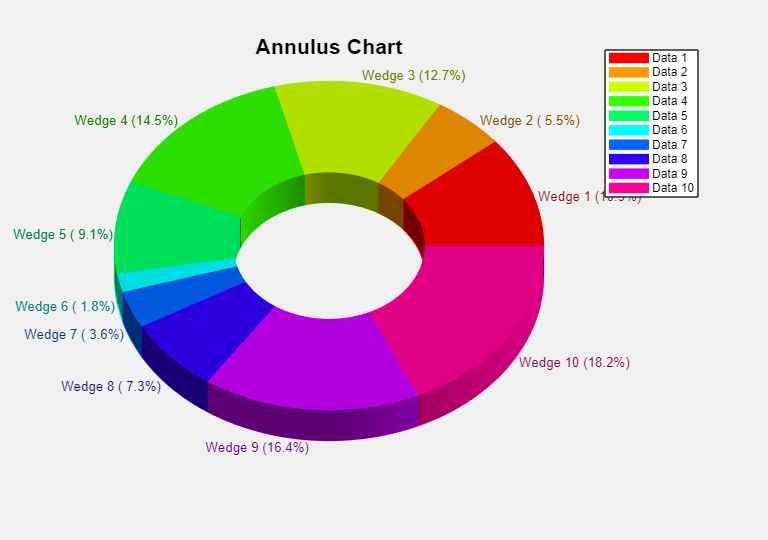

AC.LabelText = "Wedge " + (1:length( data ));

## Customize the legend and label appearance.

The legend currently obscures some of the wedge labels, so change its number of columns.

AC.LegendNumColumns = 2;

We also adjust the legend text, title, and color properties.

AC.LegendText = string( 1:length( data ) );
AC.LegendTitle = "Percentage contributions";
AC.LegendColor = "none";

Modify the percentage display in the wedge labels and legend.

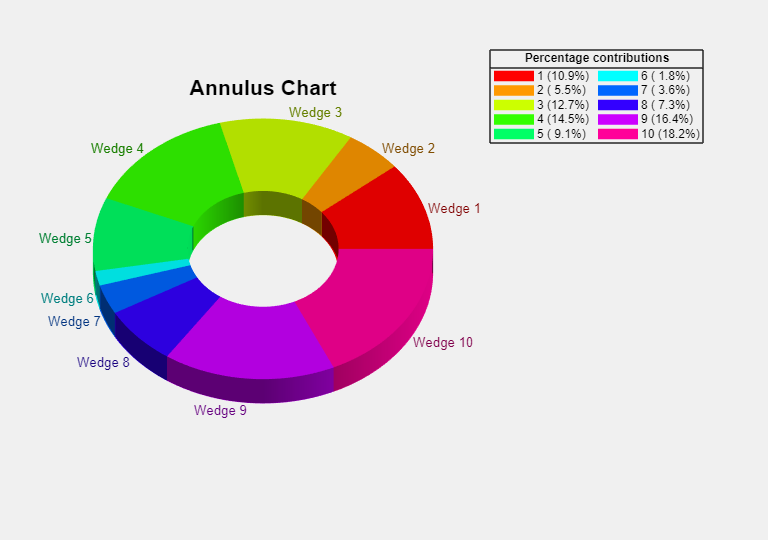

AC.LegendPercentages = "on";
AC.LabelPercentages = "off";

## Modify the chart data.

The chart data can be modified by setting the `Data` property to a new value.

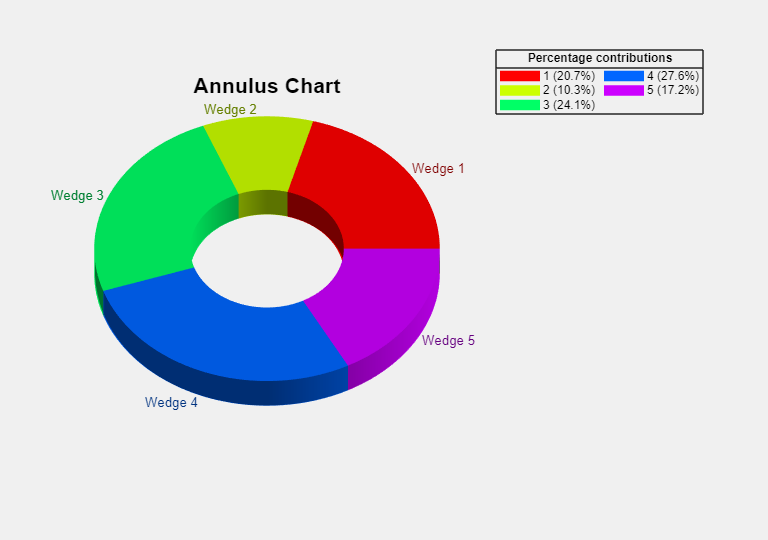

AC.Data = AC.Data(1:5);

## Define a new data vector.

The previous example set the chart data to another vector of shorter length than the original. We can also change the chart data without changing its length.

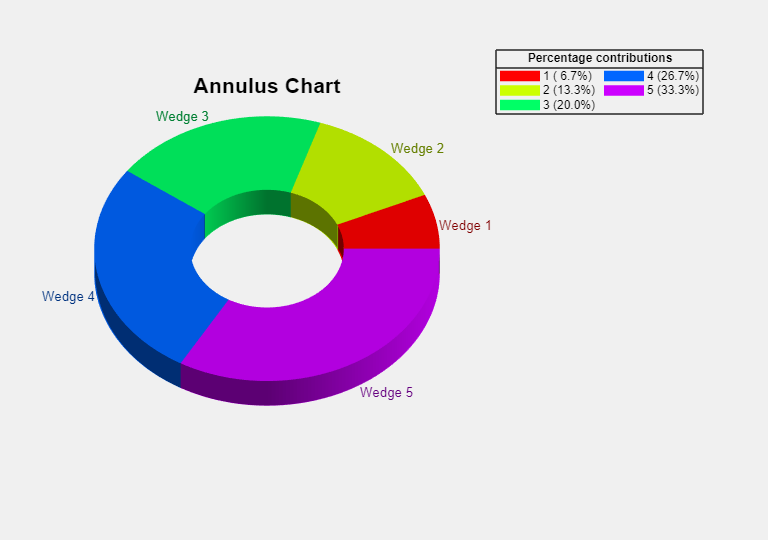

AC.Data = 1 : numel( AC.Data );

## Restore the original data.

The new chart data can also be longer than the existing data.

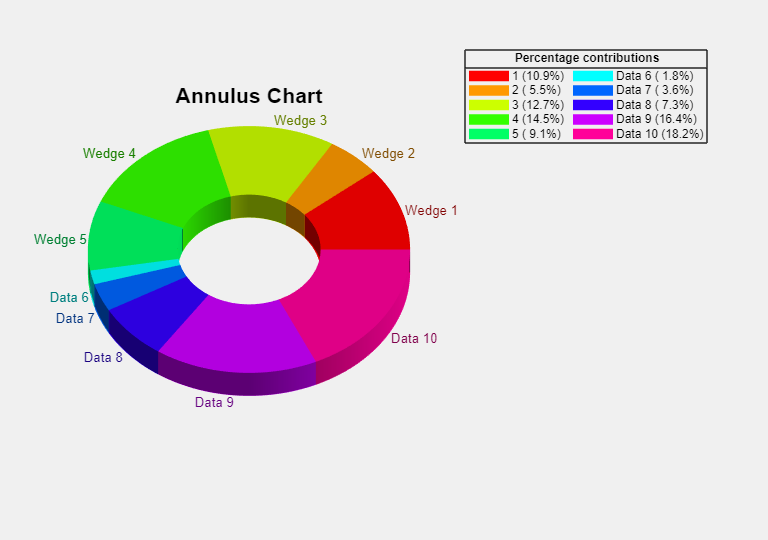

AC.Data = data;

## Restore the labels and legend text.

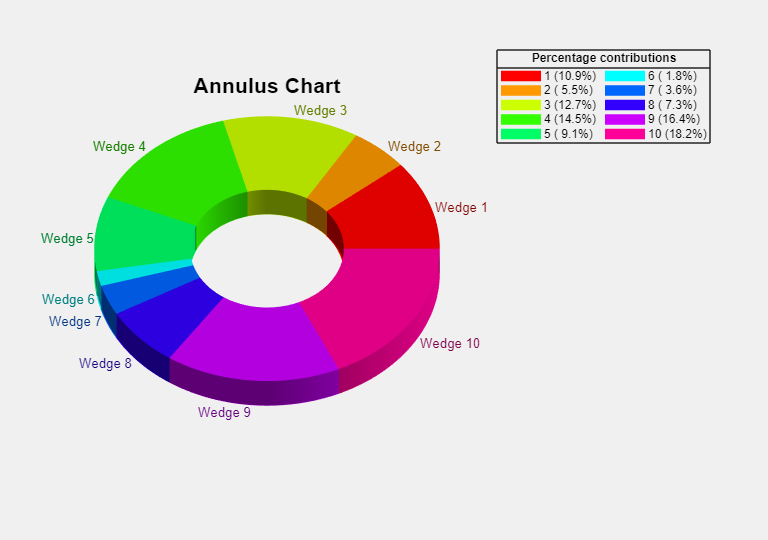

AC.LabelText = "Wedge " + (1:length( data ));
AC.LegendText = string( 1:length( data ) );

## Customize the wedge colors.

If the `FaceColor` property is not specified at the time of creation, then the chart is created using the `hsv` colormap. To change the color of the wedges, specify a new color array.

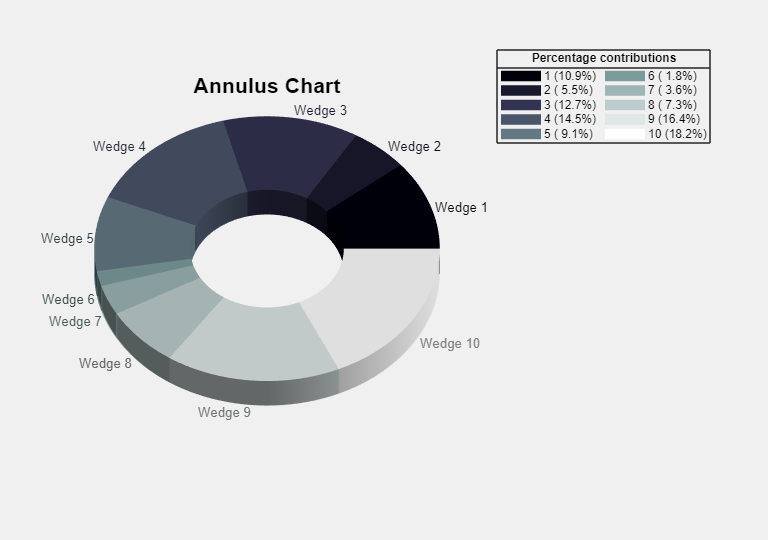

AC.FaceColor = bone( length( AC.Data ) );

## Explode the chart's wedges.

To explode the chart's wedges radially outward, set the `Exploded` property to `"on".`

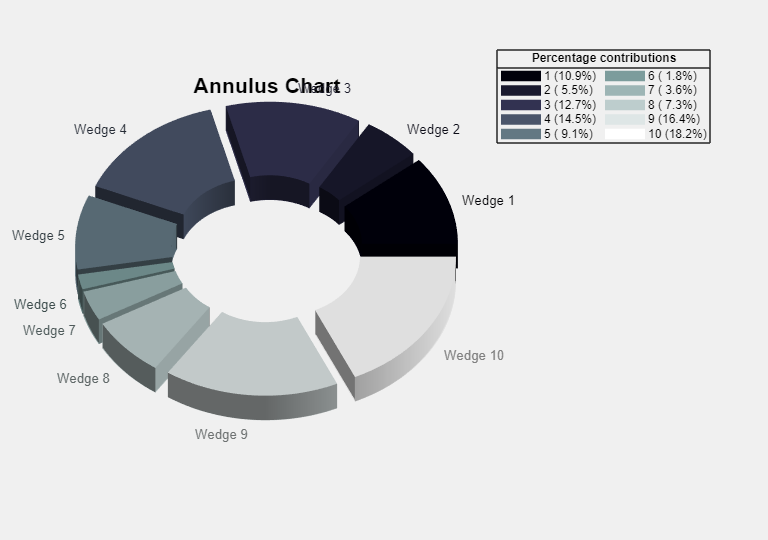

AC.Exploded = "on";

## Retract the wedges.

We retract the wedges to their original positions by setting the `Exploded` property to `"off"`.

AC.Exploded = "off";

## Hide the wedge labels.

The labels can be hidden completely.

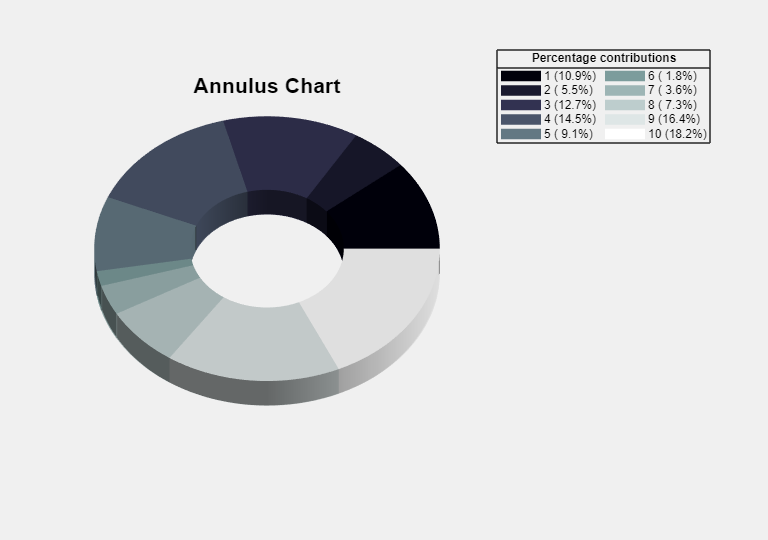

AC.VisibleLabels = "off";

## Further wedge label customization.

Let's restore the labels and make the font size slightly smaller.

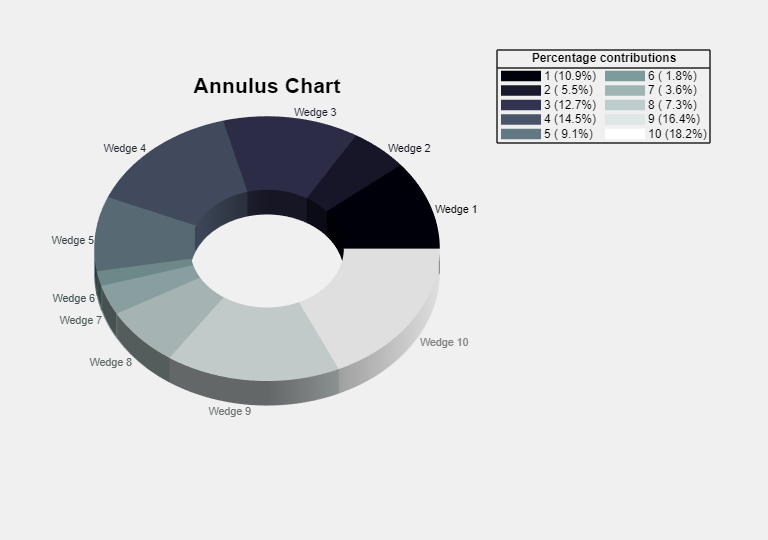

set( AC, "VisibleLabels", "on", "LabelFontSize", 8 )

## Further legend customization.

The chart provides several further properties for adjusting the legend's appearance.

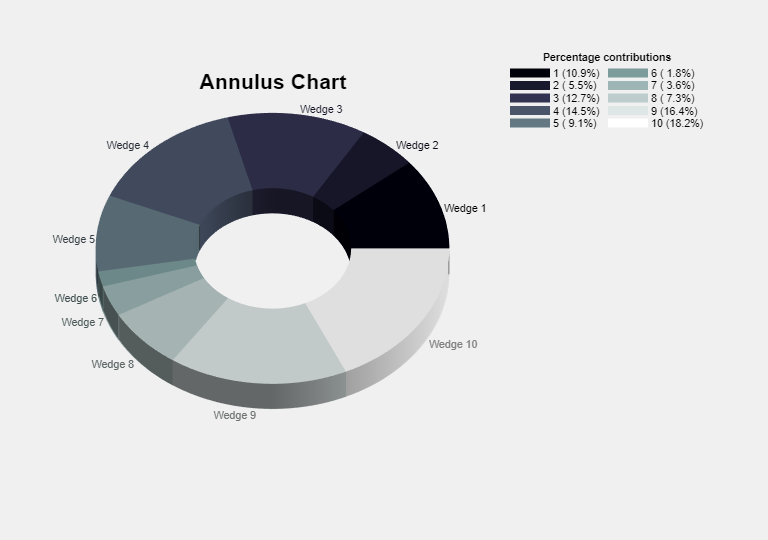

set( AC, "LegendFontSize", 8, "LegendBox", "off" )

## Specify a fixed view for the chart.

The `Annulus` chart has the `view` method for setting a specific view. For example, we can set the standard 2D view as follows.

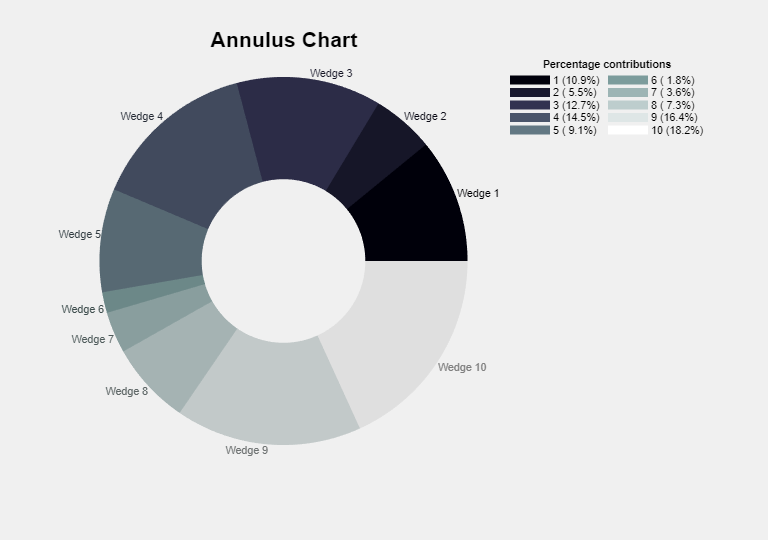

view( AC, 2 )

## Restore the default view.

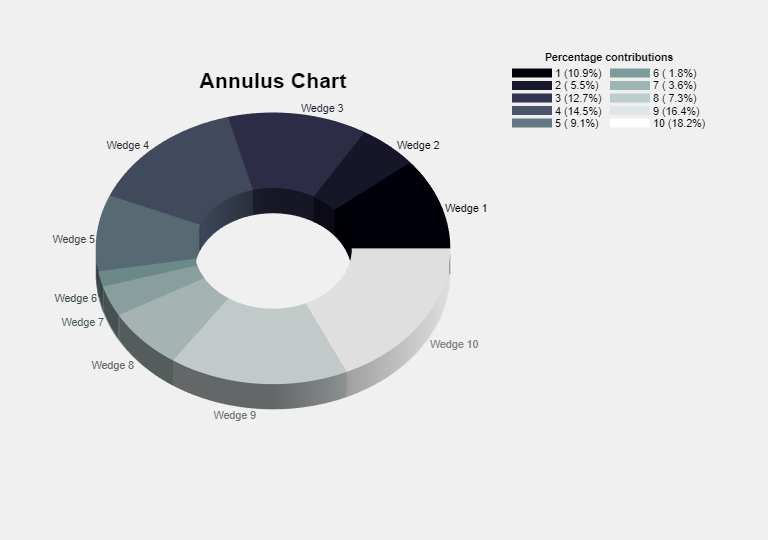

resetView( AC )

## Enable the chart's control panel.

To show the chart's control panel, we set the `Controls` property to `"on"` or use the interactive control in the axes toolbar.

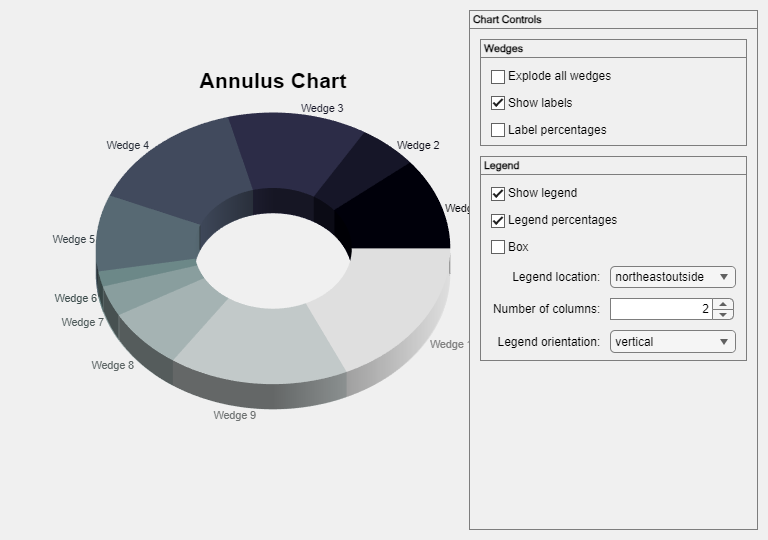

AC.Controls = "on";

*Copyright 2018-2025 The MathWorks, Inc.*